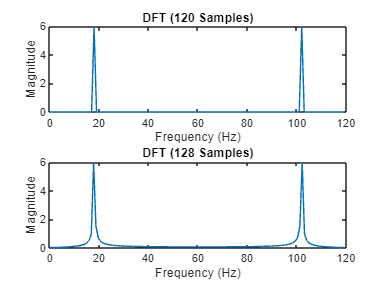

t = 0:0.01:2;
x = sin(2*pi*15*t);
y = fft(x,120);
y1 = fft(x,130);
y2 = fft(x,128);
N = length(y);
f = (0:119)*120/120;
f1 = (0:129)*120/130;
f2 = (0:127)*120/128;
subplot(2,1,1)
plot(f,abs(y)/10)
title("DFT (120 Samples)")
xlabel("Frequency (Hz)")
ylabel("Magnitude")

subplot(2,1,2)
plot(f1,abs(y1)/10)
title("DFT (130 Samples)")
xlabel("Frequency (Hz)")
ylabel("Magnitude")

%part 3
t = 0:0.01:2;
x = sin(2*pi*15*t);
y = fft(x,120);

y2 = fft(x,128);
N = length(y);
f = (0:119)*120/120;

f2 = (0:127)*120/128;
subplot(2,1,1)
plot(f,abs(y)/10)
title("DFT (120 Samples)")
xlabel("Frequency (Hz)")
ylabel("Magnitude")

subplot(2,1,2)
plot(f2,abs(y2)/10)
title("DFT (128 Samples)")
xlabel("Frequency (Hz)")
ylabel("Magnitude")

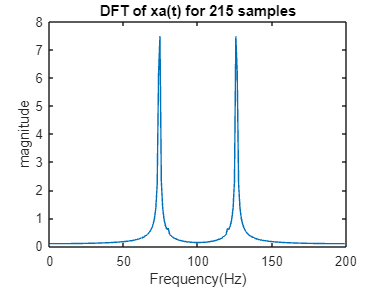

%2
n = 200;
t1 = 0:0.01:10;
x1 = 0.1*sin(120*pi*t1) + cos(126*pi*t1);
n1 = 215;
f1 = (0:n1-1)*n/n1;
y1 = fft(x1,n1);
figure
plot(f1,abs(y11)/10)
title('DFT of xa(t) for 215 samples');
xlabel('Frequency(Hz)');
ylabel('magnitude');

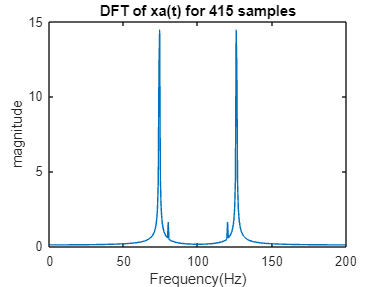


n2 = 415;
f2 = (0:n2-1)*n/n2;
y2 = fft(x1,n2);
figure
plot(f2,abs(y12)/10)
title('DFT of xa(t) for 415 samples');
xlabel('Frequency(Hz)');
ylabel('magnitude');

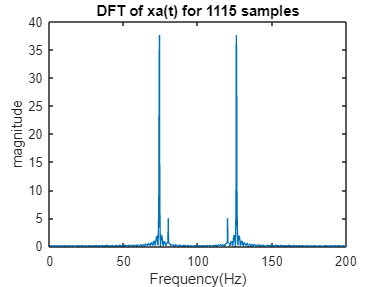


n3 = 1115;
f3 = (0:n3-1)*n/n3;
y3 = fft(x1,n3);
figure
plot(f3,abs(y13)/10)
title('DFT of xa(t) for 1115 samples');
xlabel('Frequency(Hz)');
ylabel('magnitude');

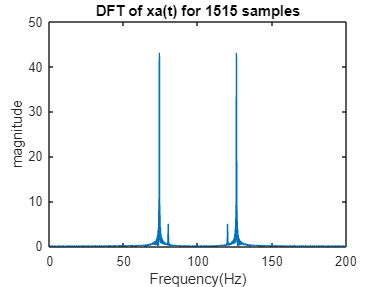


n4 = 1515;
f4 = (0:n4-1)*n/n4;
y4 = fft(x1,n4);
figure
plot(f4,abs(y14)/10)
title('DFT of xa(t) for 1515 samples');
xlabel('Frequency(Hz)');
ylabel('magnitude');

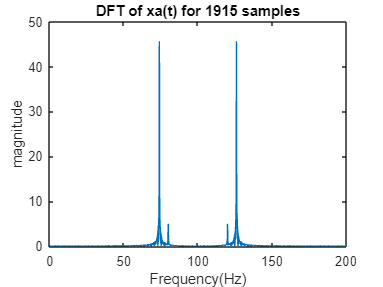


n5 = 1915;
f5 = (0:n5-1)*n/n5;
y5 = fft(x1,n5);
figure
plot(f5,abs(y15)/10)
title('DFT of xa(t) for 1915 samples');
xlabel('Frequency(Hz)');
ylabel('magnitude');

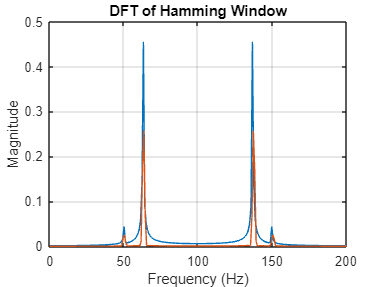

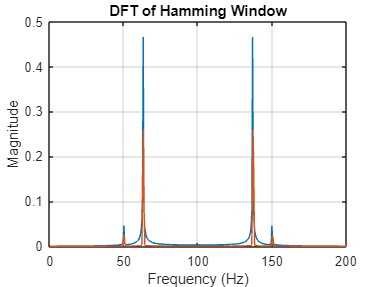

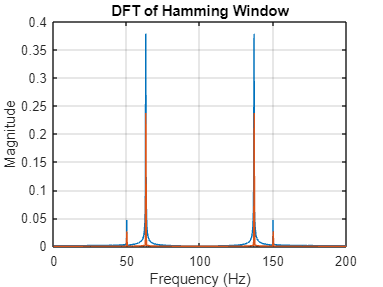

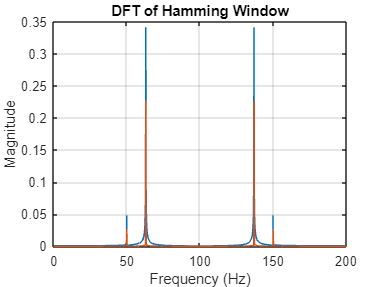

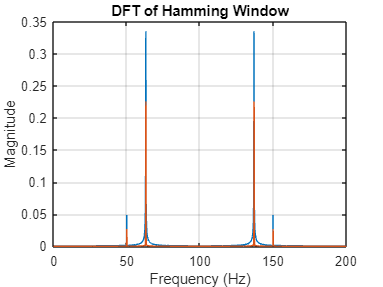

%3
A_values = 100;
B_values = 126;
duration = 10;  


t = linspace(0, duration, duration * 200);
    

signal = 0.1 * sin(A_values * pi * t) + cos(B_values * pi * t);
sample_counts = [215, 415, 1115, 1515, 1915];    
for j = 1:length(sample_counts)    
    N = sample_counts(j);
    sample_signal = signal(1:N);   
    dft = abs(fft(sample_signal)/N);
    freq_axis = (0:N-1)*200/N;   
    window = hamming(N);
    windowed_signal = signal(1:N) .* window';
    dft_windowed = abs(fft(windowed_signal))/N;
    freq_axis_windowed = linspace(0, 200, N);
    figure; 
    plot(freq_axis, dft);
    grid on;
    xlabel('Frequency (Hz)');   
    ylabel('Magnitude');
    hold on
    plot(freq_axis_windowed, dft_windowed);    
    title(sprintf('DFT of Hamming Window'));
    xlabel('Frequency (Hz)');    
    ylabel('Magnitude') 
    hold off
end    

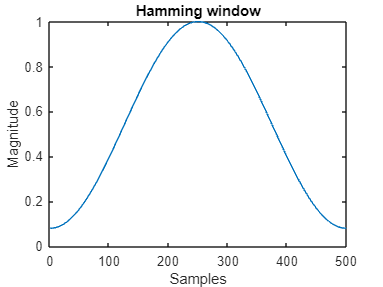

%4
z_a = readmatrix('Exp4Data1.txt');

h1 = hamming(500);

figure;
plot(h1)
title("Hamming window")
xlabel("Samples")
ylabel("Magnitude")

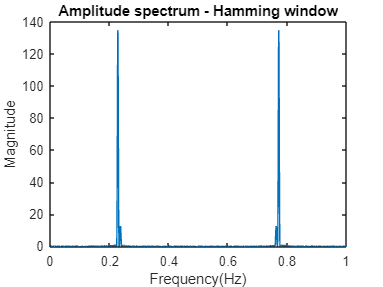


z1 = z.*(h)';
Z1 = fft(z1,10000);
fs = 1;
f= 0:fs/(length(Z1)-1):fs;

figure;
plot(f,abs(Z1))
title("Amplitude spectrum - Hamming window")
xlabel("Frequency(Hz)")
ylabel("Magnitude")

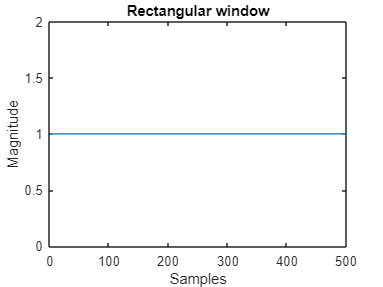


z_b = readmatrix('Exp4Data1.txt');

h2 = rectwin(500);

figure;
plot(h2)
title("Rectangular window")
xlabel("Samples")
ylabel("Magnitude")

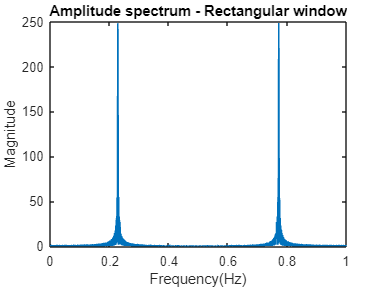


z2 = z.*(h2)';
Z2 = fft(z2,10000);
fs = 1;
f= 0:fs/(length(Z2)-1):fs;

figure;
plot(f,abs(Z2))
title("Amplitude spectrum - Rectangular window")
xlabel("Frequency(Hz)")
ylabel("Magnitude")